# 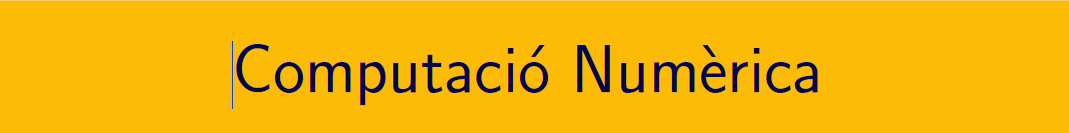

================================================================================

# Pràctica 10. Integració aproximada de funcions i dades (I).

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document .pdf i en el document **CN_exercicis_tema5_2.pdf**, els podeu trobar en el campus virtual. 

### Bloc 1. MATLAB® - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html). 

Per al mètode de Simpson, podeu fer ús de l'expressió  $ S(f,h)=\displaystyle\frac{4}{3}T\left(f,\frac{h}{2}\right)-\frac{1}{3}T(f,h)$que relaciona la fórmula dels trapezis i la regla de Simpson. També podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files) (revisar el codi)

### Bloc 2.  MATLAB® - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Bloc 3.  MATLAB® - Integració adaptativa

La partició de l'interval d'integració es construiex de tal manera que  `abs(q - Q) <= max(AbsTol,RelTol*abs(q)), amb q el valor calculat i Q el valor exacte. Consulteu `[integral](https://www.mathworks.com/help/matlab/ref/integral.html) en la documentació de MATLAB®

Cleve Moler, entre els seus codis del llibre *Numerical computing with Matlab* ens ha preparat una explicació gràfica del procediment. 

%  quadgui(@(x)humps(x),0,1,1.0e-2)
integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13)

ans = 29.8583

### Bloc 4.  MATLAB® - Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

## APRENEM .....

### Exercici 1. Aplicació dades discretes

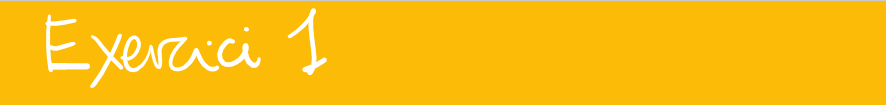

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

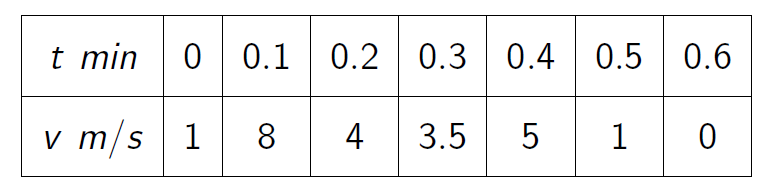

time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];

- Representa gràficament les dades de la taula

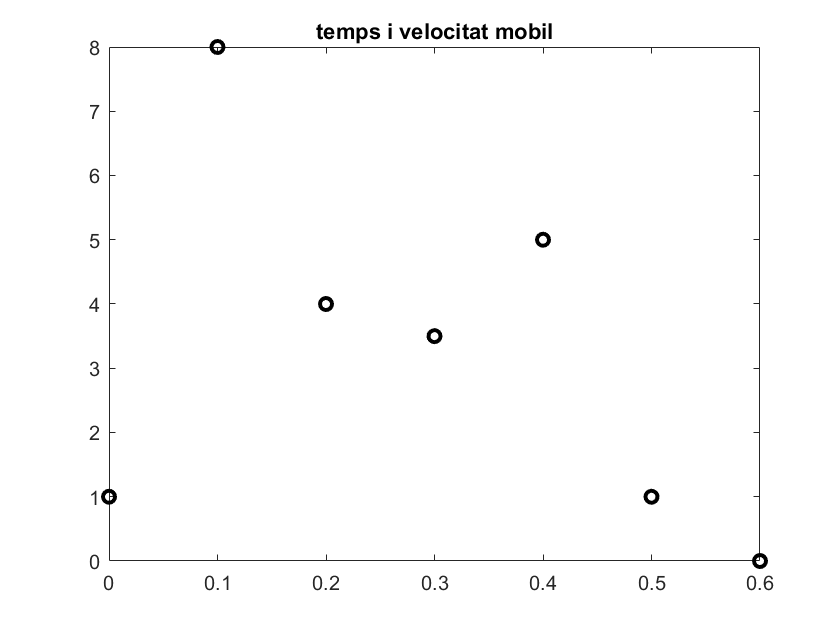

plot(time,vel,'ko', 'LineWidth',2), title('temps i velocitat mobil')

- Explica l'estratègia i dona el resultat pel mètode del punt mig

- Explica l'estratègia i dona el resultat pel mètode dels trapezis

- Explica l'estratègia i dona el resultat pel mètode de Simpson

### Exercici 2. Aplicació per funcions - Fórmules simples

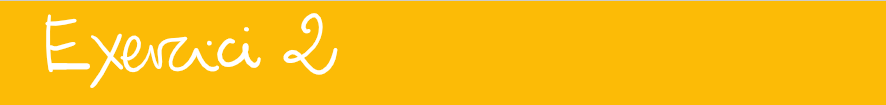

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


vc = pi/2

vc = 1.5708

f = @(x)2./(1+x.^2);

- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$(simple)

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (simple)

### Exercici 3. Aplicació per funcions - Fórmules compostes

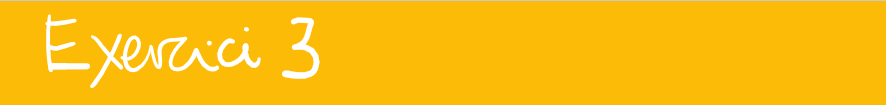

Podeu fer ús dels codis de [codis integració aproximada](http://www.math.mcgill.ca/gantumur/math578f09/?Matlab_files)

                         
$$\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,=\frac{\pi}{2}$$


clearvars;


- Calculeu, fent ús de la regla del punt mig el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

- Calculeu, fent ús de la fórmula del trapezi el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (4 subintervals)

- Calculeu, fent ús de la regla Simpson el valor de $\displaystyle \int_{0}^{1} \frac{2}{1+x^2}\, dx\,$ (2 subintervals)

### Exercici 4. Funcions amb singularitats

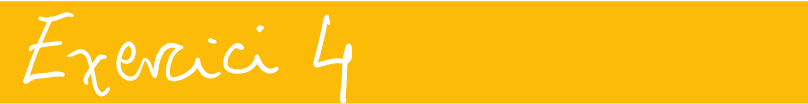

Calculeu $\displaystyle \int_0^{1} \frac{\sin t}{t}\,dt  \approx 0.946083070367 \pm 0.5e\!-\!12$

- Valor correcte

format long 
f = @(t) sin(t)./t

f = function_handle with value:
    @(t)sin(t)./t


vc = integral(f,0,1)

vc =    0.946083070367183


- Regla del punt mig composta. Quants subintervals cal pendre?

n= 64, a = 0, b = 1

n =     64


a =      0


b =      1


I_p = midp(f,a,b,n)

I_p =    0.946086134026241


- Regla dels trapezis composta. Quants subintervals cal pendre?

n= 64, a = 0, b = 1

n =     64


a =      0


b =      1


I_p = trap(f,a,b,n)

I_p =    NaN


### Exercici 5. Mètode de Romberg

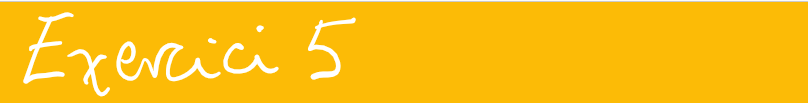

Calculeu mitjançant romberg$\displaystyle \int_0^{0.8} \frac{\sin t}{t}\,dt  \approx 0.772095 \pm 0.5e\!-\!6$

Apliqueu la taula d'extrapolació de romberg (podeu fer ús de [romberg.m](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) o un altre, verifiqueu el  vostre codi amb la taula següent)

Resposta 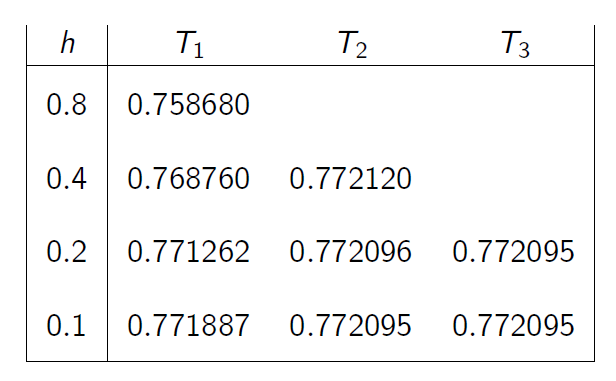

### Exercici 6. Mètode de Montecarlo

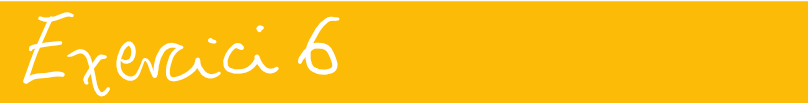

Calculeu els  valors  de    $\displaystyle\int_0^1 x dx = 1/2\,, \quad
\displaystyle\int_0^1 x^2 dx = 1/3\,, \quad
\displaystyle\int_0^4 x dx = 8\,, \quad
\displaystyle\int_{-1}^1 x dx = 1\,.

$

- Tipus I (valor esperat)

- Tipus II (hit or miss)

## AUTOAVALUACIÓ ....

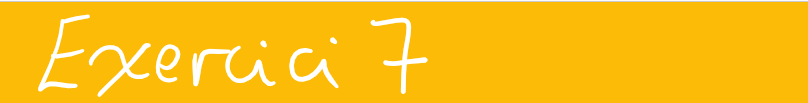

Calculeu la integral $\displaystyle I=\int_{-1}^{1} e^{-x^2}\,dx\,$

- a) Fent ús del mètode dels trapezis per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

f = @(x) exp(-x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)


a = -1; b = 1;
k = 0:5

k =      0     1     2     3     4     5


h = 1./2.^k

h =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0313


n = 2.^(k+1);
 
for k = 0:5
    t(k+1) = trap(f,a,b,n(k+1));
end
h = (b-a)./n;
disp(array2table([n;h;t]', 'VariableNames',{'Subintervals', 'Tamany subint.', 'I aproximada'}))

    Subintervals    Tamany subint.    I aproximada
    ____________    ______________    ____________

          2                  1           1.3679   
          4                0.5           1.4627   
          8               0.25            1.486   
         16              0.125           1.4917   
         32             0.0625           1.4932   
         64            0.03125           1.4935   



- b) Fent ús del mètode de Simpon per $$h=\displaystyle\frac{1}{2^k},\ \ 0\leq k\leq 5.$

f = @(x) exp(-x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)


a = -1; b = 1;
k = 0:5

k =      0     1     2     3     4     5


h = 1./2.^k

h =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0313


n = 2.^(k);
 
for k = 0:5
    s(k+1) = simp(f,a,b,n(k+1));
end
h = (b-a)./n;
disp(array2table([n;h;s]', 'VariableNames',{'Subintervals', 'Tamany subint.', 'I aproximada'}))

    Subintervals    Tamany subint.    I aproximada
    ____________    ______________    ____________

          1                  2           1.5786   
          2                  1           1.4944   
          4                0.5           1.4937   
          8               0.25           1.4937   
         16              0.125           1.4936   
         32             0.0625           1.4936   



- c) Apliqueu el mètode de Romberg, fent ús dels resultats de l'apartat a) 

r = 4;  % r(k) nombre de files per fer extrapolacions 
 
for k = 0:5
    R = romberg(f,a,b,r);
end
h = (b-a)./n;
disp(array2table(R, 'VariableNames',{'extra1', 'extra2', 'extra3', 'extra4'}))

    extra1     extra2    extra3    extra4
    _______    ______    ______    ______

    0.73576         0         0         0
     1.3679    1.5786         0         0
     1.4627    1.4944    1.4887         0
      1.486    1.4937    1.4937    1.4937



- d) Fent ús de mètodes de simulació de MonteCarlo, per mostres de tamany $$M={10^k},\ \ 1\leq k\leq 7.$$

- e)  Doneu els decimals exactes i les xifres significatives del les vostres aproximacions, sabent que  $$\displaystyle\int_0^t e^{-x^2}\,dx\, = \sqrt{\pi}\,erf\left(t\right).$$ Consulteu l'ajuda de Matlab per la funció `erf.`

`Document preparat per M. Àngela Grau Gotés - 3 de maig de 2023`

% Codis de les funcions 